% UP  ->  overshoot    ->  Ultrapassagem percentual
% Tp  ->  peaktime     ->  Instante de Pico
% Ts  ->  settlingtime ->  Tempo de Acomodação
% Tr  ->  risetime     ->  Tem de Subida
%2
%a)
G = tf(16,[1 3 16])

G =
 
        16
  --------------
  s^2 + 3 s + 16
 
Continuous-time transfer function.
Model Properties


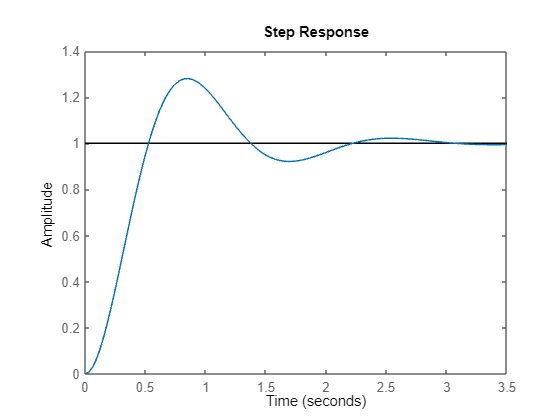

step(G)

stepinfo(G)

ans = struct with fields:
         RiseTime: 0.3569
    TransientTime: 2.6570
     SettlingTime: 2.6570
      SettlingMin: 0.9213
      SettlingMax: 1.2803
        Overshoot: 28.0255
       Undershoot: 0
             Peak: 1.2803
         PeakTime: 0.8596


%b)
G = tf(0.04,[1 0.02 0.04])

G =
 
         0.04
  -------------------
  s^2 + 0.02 s + 0.04
 
Continuous-time transfer function.
Model Properties


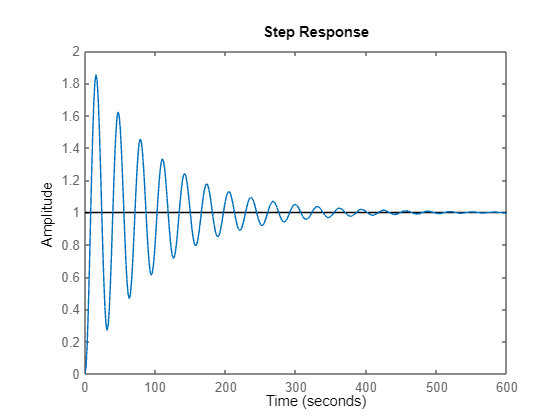

step(G)

stepinfo(G)

ans = struct with fields:
         RiseTime: 5.4160
    TransientTime: 380.0163
     SettlingTime: 380.0163
      SettlingMin: 0.2699
      SettlingMax: 1.8545
        Overshoot: 85.4461
       Undershoot: 0
             Peak: 1.8545
         PeakTime: 15.7080


%c)
G = tf(10500000,[1 1600 10500000])

G =
 
         1.05e07
  ----------------------
  s^2 + 1600 s + 1.05e07
 
Continuous-time transfer function.
Model Properties


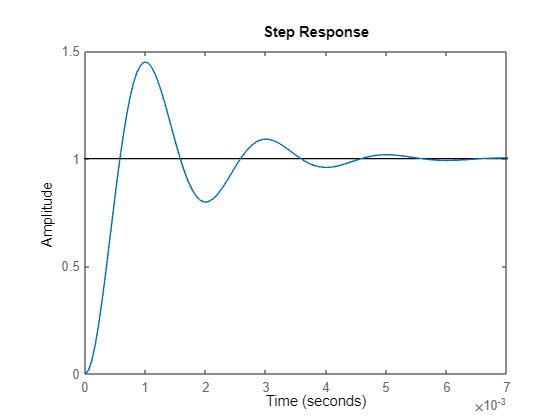

step(G)

stepinfo(G)

ans = struct with fields:
         RiseTime: 3.9036e-04
    TransientTime: 0.0044
     SettlingTime: 0.0044
      SettlingMin: 0.7985
      SettlingMax: 1.4480
        Overshoot: 44.8011
       Undershoot: 0
             Peak: 1.4480
         PeakTime: 9.7860e-04


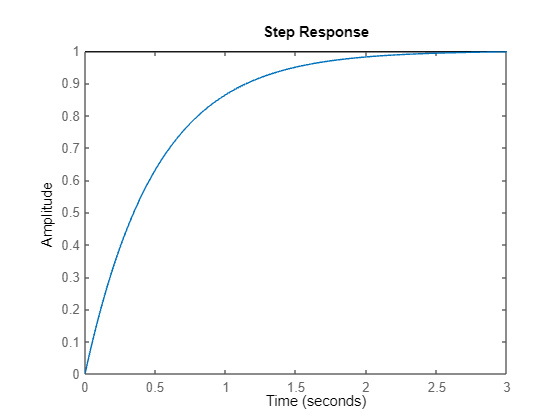


%3
a = tf(2,[1 2]);
step(a)

roots([1 2])

ans = -2

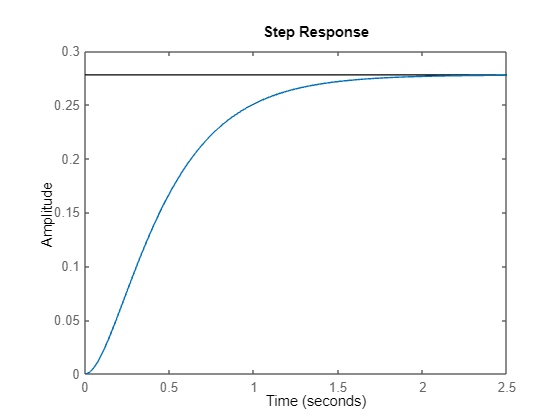


b = tf(5,[1 9 18]);
step(b)

roots([1 9 18])

ans =     -6
    -3



c = tf([10 17],[1 30 200])

c =
 
     10 s + 17
  ----------------
  s^2 + 30 s + 200
 
Continuous-time transfer function.
Model Properties


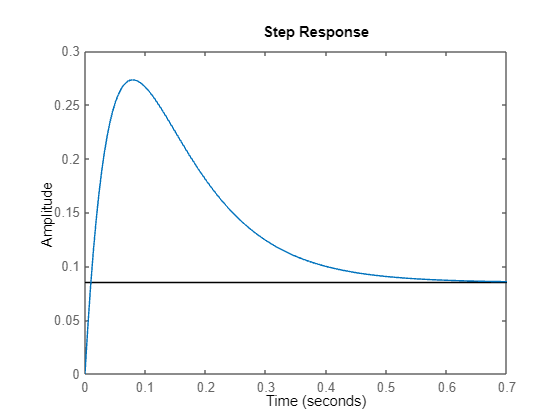

step(c)

roots([10 17])

ans = -1.7000

roots([1 30 200])

ans =    -20
   -10



d = tf([20],[1 6 144])

d =
 
        20
  ---------------
  s^2 + 6 s + 144
 
Continuous-time transfer function.
Model Properties


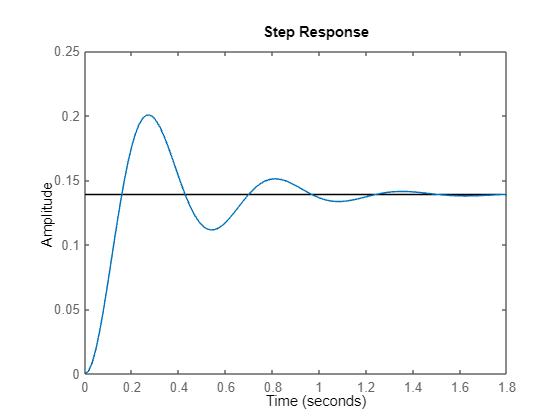

step(d)

roots([1 6 144])

ans =   -3.0000 +11.6190i
  -3.0000 -11.6190i



e = tf([1 2],[1 0 9])

e =
 
   s + 2
  -------
  s^2 + 9
 
Continuous-time transfer function.
Model Properties


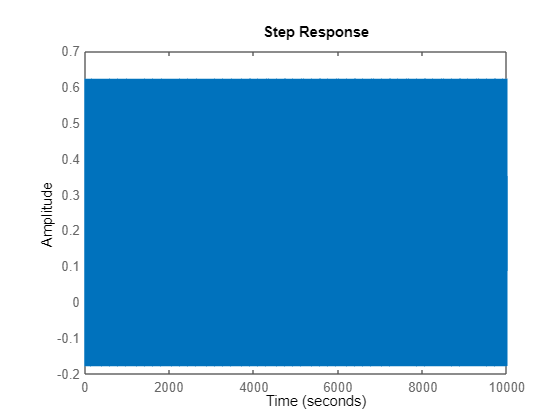

step(e)

roots([1 2])

ans = -2

roots([1 0 9])

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i



f = tf([1 5],[1 20 100])

f =
 
       s + 5
  ----------------
  s^2 + 20 s + 100
 
Continuous-time transfer function.
Model Properties


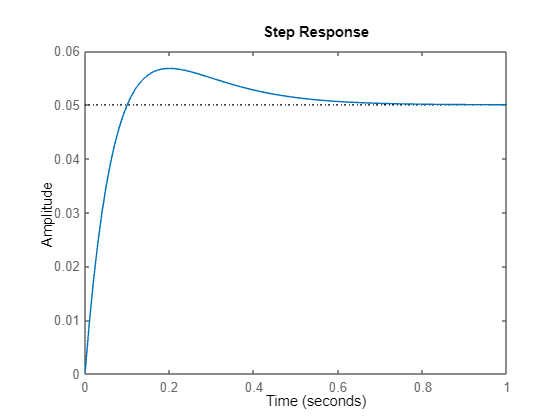

step(f)

roots([1 5])

ans = -5

roots([1 20 100])

ans =    -10
   -10




%4
v = tf(0.2380,[1 0.2380]);
stepinfo(v)

ans = struct with fields:
         RiseTime: 9.2311
    TransientTime: 16.4373
     SettlingTime: 16.4373
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 30.7656
